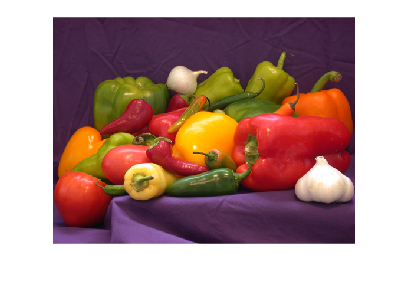

clear;
% I_rgb = imread('peppers.png')
% I_rgb = im2double(I_rgb)
% I_hsv = rgb2hsv(I_rgb)


I_rgb = imread("peppers.png");
imshow(I_rgb)

I_rgb

I_rgb = 384×512×3 uint8 数组
I_rgb(:,:,1) =

    62    63    63    65    66    63    61    63    63    64    64    61    65    64    61    62    63    65    65    64    61    64    65    64    66    71    67    65    64    62    68    68    70    70    71    70    68    74    74    70    70    71    71    72    74    70    69    70    67    67    67    69    69    66    67    67    71    70    69    67    68    71    69    70    71    71    71    70    67    68    67    60    57    56    51    46    45    51    54    54    55    58    54    54    57    58    60    60    58    59    57    60    63    67    70    69    70    70    69    71    70    67    68    69    66    67    68    66    67    64    63    65    66    66    65    62    62    66    66    64    63    64    62    65    67    61    64    64    65    65    62    61    65    68    67    65    70    70    65    66    68    68    67    70    70    72    70    70    70    68    70    71    71    71    68    71    73    71    69   

I_hsv = rgb2hsv(I_rgb);
yellow_upper = [26, 43, 43]./255

yellow_upper =     0.1020    0.1686    0.1686


yellow_lower = [34, 255, 255]./255

yellow_lower =     0.1333    1.0000    1.0000


I_hsv = inRange(I_hsv, yellow_lower, yellow_upper)

对于此运算，数组的大小不兼容。

出错 inRange (第 4 行)
    if all(hsv <= upper) && all(hsv >= lower)

相关文档

repmat

ori_grey = [1,23]

ori_grey =      1    23


ori_grey([1,2]) = 0

ori_grey =      0     0
